clear
clc

opts = optimoptions('fmincon','SpecifyObjectiveGradient',true,'Display','iter');

tic
[xv,Rv] = fmincon(@(x) objective(x),[10 8/3 28 1 1 1],[],[],[],[],[0 0 0 -10 -10 -10],[30 30 30 10 10 10],[],opts)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    7.236144e+02    0.000e+00    9.004e+03
    1       3    3.545922e+02    0.000e+00    7.096e+04    6.677e+00
    2      23    3.491483e+02    0.000e+00    5.033e+04    7.627e-05
    3      25    3.491216e+02    0.000e+00    5.060e+04    5.670e-04
    4      27    3.281781e+02    0.000e+00    6.404e+03    7.137e+00
    5      31    1.854845e+02    0.000e+00    1.017e+03    6.619e-01
    6      34    1.580354e+02    0.000e+00    4.692e+03    2.494e+00
    7      47    1.429104e+02    0.000e+00    1.577e+03    1.918e-02
    8      49    1.393737e+02    0.000e+00    4.059e+03    1.350e-01
    9      55    1.391840e+02    0.000e+00    3.606e+03    1.261e-01
   10      56    7.727523e+01    0.000e+00    6.546e+01    2.429e+01
   11      57    7.172688e+01    0.000e+00    3.021e+01    1.417e+00
   12      58    4.874713e+01    0.000e+00    5

xv =    15.7329    0.4169    0.0333   -5.3921    9.8840   -5.4486


Rv = 0.0238

toc

Elapsed time is 204.191078 seconds.


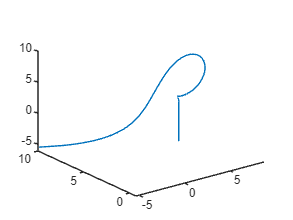

A = AutoDiff([xv(1) xv(2) xv(3) xv(4) xv(5) xv(6)]);

[tf, yf] = ODE.rkf45(@(t,y) ODE.test.LorenzRHS(t,y,A(1),A(2),A(3)), [A(4);A(5);A(6)], 0, 10, 0.01,  1e-9, A);

L = sum((yf{end} - [0;0;0]).^2);

dL = full(getderivs(L));
L = getvalue(L);

for i = 1:length(tf)
    yfv(:,i) = getvalue(yf{i});
    dyfv(:,:,i) = full(getderivs(yf{i}));
end

figure
plot3(yfv(1,:),yfv(2,:),yfv(3,:))

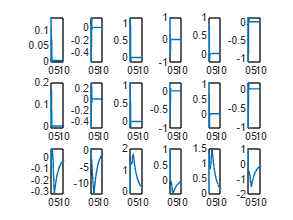


[nx,ny,~] = size(dyfv);

figure
k=0;
for i = 1:nx
    for j = 1:ny
        k=k+1;
        subplot(nx,ny,k)
        plot(tf,squeeze(dyfv(i,j,:)))
    end
end

function [L,dL] = objective(x)

A = AutoDiff([x(1) x(2) x(3) x(4) x(5) x(6)]);

[~, yf] = ODE.rkf45(@(t,y) ODE.test.LorenzRHS(t,y,A(1),A(2),A(3)), [A(4);A(5);A(6)], 0, 10, 0.01,  1e-4, A);

L = sum((yf{end} - [0;0;0]).^2);

dL = full(getderivs(L));
L = getvalue(L);

end